M = 0.375;
m = 0.279;
b = 0.1;
I = 0.0034;
g = 9.8;
l = 0.11;
q = (M+m)*(I+m*l^2)-(m*l)^2;
s = tf('s');

P_cart = (((I+m*l^2)/q)*s^2 - (m*g*l/q))/(s^4 + (b*(I + m*l^2))*s^3/q - ((M + m)*m*g*l)*s^2/q - b*m*g*l*s/q);

P_pend = (m*l*s/q)/(s^3 + (b*(I + m*l^2))*s^2/q - ((M + m)*m*g*l)*s/q - b*m*g*l/q);

sys_tf = [P_cart ; P_pend];

inputs = {'u'};
outputs = {'x'; 'phi'};

set(sys_tf,'InputName',inputs)
set(sys_tf,'OutputName',outputs)

sys_tf

sys_tf =
 
  From input "u" to output...
                        8.251e-08 s^2 - 3.662e-06
   x:  -----------------------------------------------------------
       4.249e-08 s^4 + 8.251e-09 s^3 - 2.395e-06 s^2 - 3.662e-07 s
 
                               3.737e-07 s
   phi:  -------------------------------------------------------
         4.249e-08 s^3 + 8.251e-09 s^2 - 2.395e-06 s - 3.662e-07
 
Continuous-time transfer function.



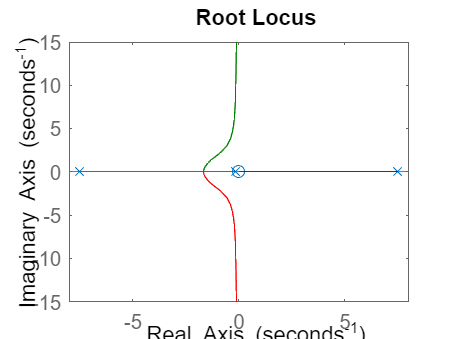


rlocus(P_pend)